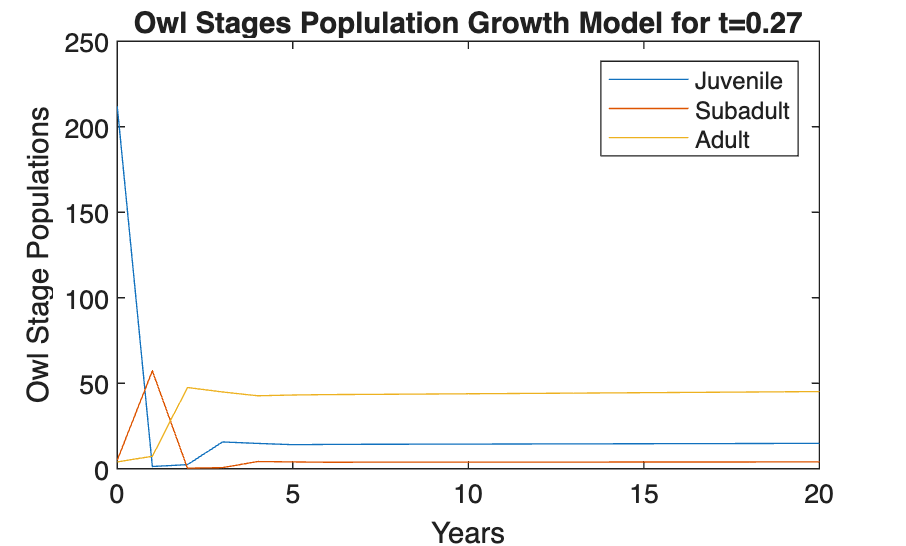

clear
t = 0.27; % Parameter value
A = [0 0 0.33;t 0 0;0 0.71 0.94]; % Transition matrix
v0 = [212;5;4]; % Initial state vector, based on M21200504

% Looping data over 20 years
x = v0;
P = x; % Matrix containing the state vectors over 20 years
for i=1:20
    x = A * x;
    P = [P x]; % Augmenting P with each new state vector x
end

years=0:20;
plot(years, P)
xlabel("Years")
ylabel("Owl Stage Populations")
title("Owl Stages Poplulation Growth Model for t=0.27")
legend( ...
    "Juvenile", ... % Blue -> Juvenile
    "Subadult", ... % Red -> Subadult
    "Adult"... % Yellow -> Adult
)